# SVM na base Optical Digits

## Preparação inicial

clear; close all force; clc;
rng(1); % Para reproduzir os resultados

## Configurações

CLASSES = 10;
ATRIBUTOS = 64;
ITERACOES = 5;
CONSTANTE_SVM = 1;
KERNEL = 'linear';
USANDO_PCA = false;
VARIANCIA_PCA = 0.8;
PERCENTUAL_TESTE = 0.3;

## Importação e processamento inicial da base

data = csvread('training.csv'); %csvread('testing.csv')];

O número 1 será somado às classes para ajustá-las aos índices do MATLAB. Isso significa que o número 0 da base corresponde à classe 1, o número 1 à classe 2, e assim sucessivamente.

all_classes = data(:, size(data, 2)) + 1;


Usando PCA, a fim de diminuir a quantidade de atributos, logo, a complexidade.

if USANDO_PCA
    all_features = PCA(data(:, 1:ATRIBUTOS), VARIANCIA_PCA);
else
    all_features = data(:, 1:ATRIBUTOS);
end

## Particionamento da base usando a estratégia Hold-Out

p = cvpartition(all_classes, 'HoldOut', PERCENTUAL_TESTE);

## Armazenagem dos resultados

Vetor para armazenar os acertos de cada iteração.

hits = zeros(1, ITERACOES);


Vetor para armazenar o tempo em cada iteração.

times = zeros(1, ITERACOES);


Array de matrizes com o resultado esperado de cada iteração, na primeira coluna; ao lado do resultado obtido, na segunda coluna.

results = zeros(p.TestSize, 2, ITERACOES);

## Loop principal

## Inicialização do laço

tic;
for i=1:ITERACOES
    t = tic;

## Separação das amostras de treino

    train_idx = training(p);
    train_features = all_features(train_idx, :);
    train_classes = all_classes(train_idx);

## Treina array de modelos SVM, um para cada classe (1 vs ALL)

    models = cell(CLASSES, 1);
    for j = 1:CLASSES
        f = train_features;
        c = train_classes == j;
        models{j} = fitcsvm(f, uint8(c)*j,...
            'KernelFunction', KERNEL, 'BoxConstraint', CONSTANTE_SVM,...
            'Standardize', true, 'ClassNames', {int2str(0), int2str(j)});
    end

## Separação das amostras de teste

    test_idx = test(p);
    test_features = all_features(test_idx, :);
    expected_output = all_classes(test_idx);

## Cálculo das predições

Produz array com as predições dos modelos.

    model_predictions = zeros(p.TestSize, CLASSES);
    
    for j=1:CLASSES
        [label, score] = predict(models{j}, test_features);
        model_predictions(:, j) = score(:, 2);
    end

  O modelo com a maior predição será o escolhido.

    [~, predictions] = max(model_predictions, [], 2);

Guarda os resultados de cada iteração e soma a quantidade de acertos.

    results(:, 1, i) = expected_output;
    results(:, 2, i) = predictions;
    hits(i) = sum(uint8(predictions == expected_output));

Reparticiona para proximo teste.

    p = repartition(p);

Armazena tempo de execucao e finaliza o laço.

    times(i) = toc(t);
end

## Plota gráfico das 3 primeiras componentes principais

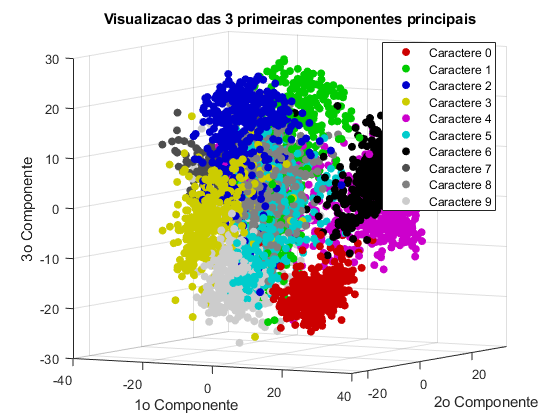

visualizacao_pca(data(:, 1:ATRIBUTOS), all_classes, CLASSES);

## Plota erros das iterações executadas

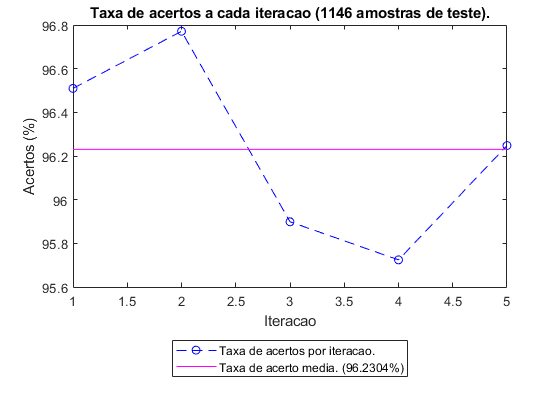

figure;
accuracy = hits * 100 / p.TestSize;
accuracy = accuracy(1:i);
plot(1:i, accuracy, 'bo--');
hold on;
x = linspace(1, i);
plot(x , mean(accuracy) * ones(1, length(x)), 'm-')
hold off;
legend('Taxa de acertos por iteracao.', "Taxa de acerto media. (" + mean(accuracy(1:i)) + "%)", 'Location', 'southoutside');
title("Taxa de acertos a cada iteracao (" + p.TestSize + " amostras de teste).");
xlabel('Iteracao');
ylabel('Acertos (%)');

## Plota tempo das iterações executadas

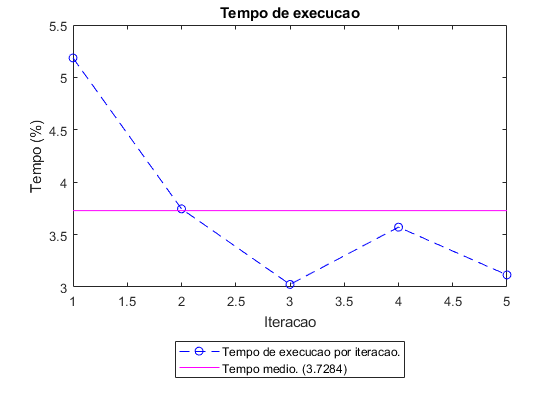

figure;
plot(1:i, times(1:i), 'bo--');
hold on;
x = linspace(1, i);
plot(x , mean(times(1:i)) * ones(1, length(x)), 'm-')
hold off;
legend('Tempo de execucao por iteracao.', "Tempo medio. (" + mean(times(1:i)) + ")", 'Location', 'southoutside');
title("Tempo de execucao");
xlabel('Iteracao');
ylabel('Tempo (%)');

## Plota matriz de confusão média.

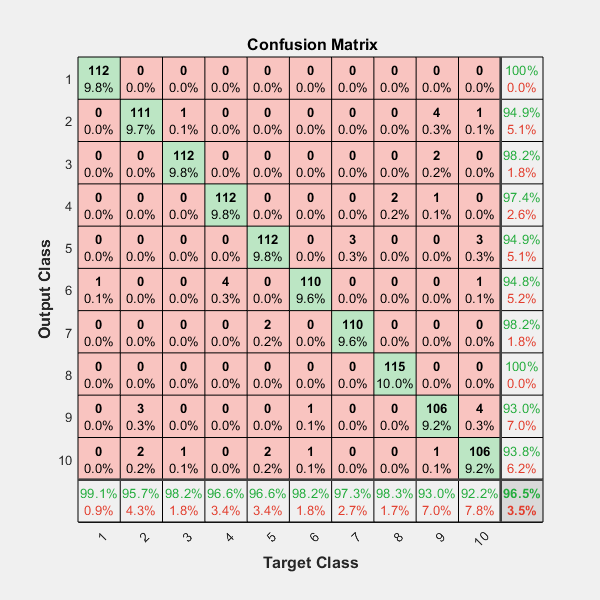

figure;
r = floor(mean(results, ITERACOES));
targets = zeros(CLASSES, p.TestSize);
outputs = zeros(CLASSES, p.TestSize);
subs = 1:p.TestSize;
targets_idx = sub2ind(size(targets), r(:, 1), subs');
outputs_idx = sub2ind(size(outputs), r(:, 2), subs');
targets(targets_idx) = 1;
outputs(outputs_idx) = 1;
plotconfusion(targets, outputs);